**Skills 1 Part 1: David Ramotowski**

First let's generate some data to play with ...

 To generate a uniform random number between 0 and 1 we can write:

x=rand

x = 0.3050

This statement generates a row vector with 5 random numbers

x=rand(1,5)

x =     0.2084    0.6156    0.7937    0.6722    0.2152


 To get a column vector we can transpose

x'

ans =     0.2084
    0.6156
    0.7937
    0.6722
    0.2152


To generate a matrix of random numbers with 3 rows and 5 columns we write

x=rand(3,5)

x =     0.6780    0.8108    0.8811    0.0974    0.1277
    0.1042    0.9657    0.5704    0.0920    0.6336
    0.6942    0.8292    0.9193    0.7022    0.9782


For a 3 by 3 square matrix we can write ...

x=rand(3,3)

x =     0.3171    0.3368    0.2222
    0.5703    0.6305    0.3805
    0.3029    0.8650    0.2163


or more simply

x=rand(3)

x =     0.4423    0.1534    0.9471
    0.4941    0.8883    0.3949
    0.7637    0.9620    0.7807


If we want Nx=1,00 data points we can write

Nx=1e3; % i.e. Nx=1*10^3=1,000
x=rand(1,Nx);

This data set is too big to look at on the screen, so we can plot it instead

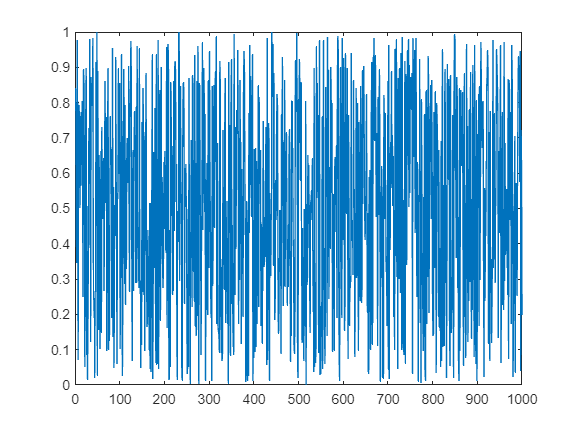

plot(x);

By default Matlab plots the points connected by lines, but here this is innapropriate, so we plot the data as points instead

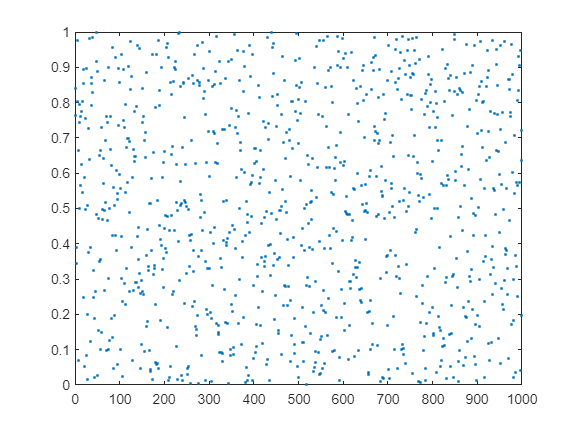

plot(x,'.');

Here the second argument to 'plot' is a format string '.', which is one example of many different plotting styles. Type 'help plot' to see all the available plotting styles (or look up 'plot' in the help window).

----------------------- Histograms -------------------------------------

A better way to look at univariate data is with a histogram. To display a histogram over 10 uniformly spaced bins we write

hist(x,10)

To see what we're looking at, we should really label the plot

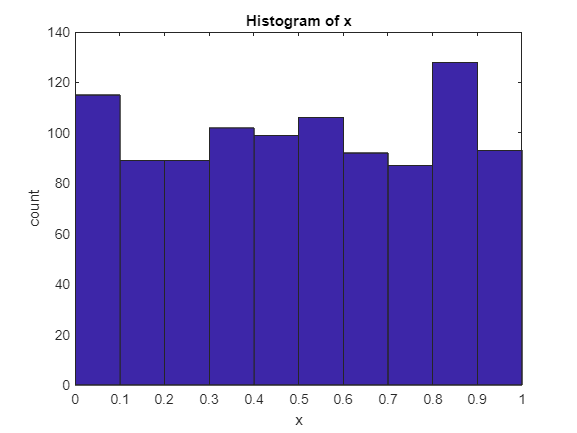

xlabel('x'); ylabel('count'); title('Histogram of x');

We can compute the probability distribution similarly, but with a few more commands

[count,bins]=hist(x,10);
Pr=count/Nx;

Note that the sum of count is equal to Nx, but the sum of Pr is equal to1, i.e.

sum(count)

ans = 1000

sum(Pr)

ans = 1.0000

Also note that the 'bins' vector contains the 10 uniformly spaced bins, which were calculated by 'hist'

bins

bins =     0.0510    0.1509    0.2508    0.3507    0.4506    0.5505    0.6503    0.7502    0.8501    0.9500


To make a histogram-style plot of Pr, we can write (see 'help bar'):

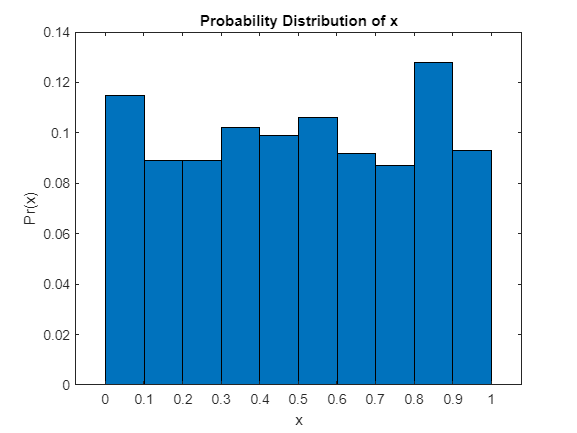

bar(bins,Pr,1); xlabel('x'); ylabel('Pr(x)'); 
title('Probability Distribution of x');

----------------------- Basic Statistics -------------------------------

Now we will compute the mean of the data using three different methods to show how Matlab works

First we use a loop, which is a classic approach ...

xavg=0;
for i=1:Nx
    xavg=xavg+x(i);
end
xavg=xavg/Nx

xavg = 0.5038

Second we use a 'vectorized' approach, which is more typical Matlab approach ...

xavg2=sum(x)/Nx

xavg2 = 0.5038

Third we can use the built in Matlab function ...

xavg3=mean(x)

xavg3 = 0.5038

Now we will compute the variance of the data using two different methods to show how Matlab works

We can compute the variance using the definition ...

xdev=x-xavg;
xvar=mean(xdev.^2)

xvar = 0.0855

Note: the '^' is used to raise a number to a power, e.g.

3^2

ans = 9

Note: the '.^' is used to raise a vector to a power, e.g.

(1:3).^2

ans =      1     4     9


Note: in Matlab the '*','/', and '^' operators by default attempt to use linear algebra, or 'matrix' products, so the following produces an error

(1:3)^2

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each element of the matrix individually, use POWER (.^) for elementwise
power.

You must use the '.*','./', and '.^' operators to get the element-by-element, or 'array' products.

More simply we can compute the variance using the built in matlab function

xvar2=var(x)

xvar2 = 0.0803

Note that the slight discrepancy between xvar and xvar2 is because 'var' uses the sample variance formula, i.e. the second 'mean' uses Nx-1 rather than Nx in the denominator, so we have

err=xvar-xvar2

err = 0.0052

err=xvar-xvar2*(Nx-1)/Nx

err = 0.0053

It is important to understand that in Matlab, or in any computer-based calculation, decimal numbers can only be represented with a finite precision. This means that there are only a finite number of digits used. In Matlab numbers are double precision by default, which means there are approximately 16 digits stored. The minimum distance between two numbers is given by 

eps

ans = 2.2204e-16

If you happen to be familiar with linear algebra, a third way to compute the variance is to use a dot product

xvar3=xdev*xdev'/(Nx-1)

xvar3 = 0.0855

the multivariate generalization of this approach can be used to efficiently compute the covariance matrix for a large data set

Matlab has built in functions for other simple statistics, i.e.

std(x)

ans = 0.2833

median(x)

ans = 0.5075

skewness(x)

ans = 0.0190

kurtosis(x)

ans = 1.8251

max(x)

ans = 0.9996

min(x)

ans = 0.0012

Note that Matlab has no function to compute the most common value, or mode, of a data set. To do this you can take one of two routes:

For continuous data, you can use a histogram

Nbin=15;
[cnt,bins]=hist(x,Nbin);
[maxcnt,imax]=max(cnt);
xmode=bins(imax)

xmode = 0.7001

Note that for a good estimate, you will need many bins, as this only localizes the mode to within a bin. To do this you will need a lot of data however, because a histogram with too many bins will be unreliable

For instance, say we have some Gaussian random numbers

x=randn(1,Nx); % Nx numbers from a zero-mean, unit-variance normal distribution
% see 'help randn'

A small number of bins shows the 'bell-curve' pattern of the data well

hist(x,Nx/10);

But a large number of bins shows the data as nearly uniform!

hist(x,Nx*10);

For discrete data we can use the same approach ... almost.

x=unidrnd(5,1,Nx) % generate integer random numbers between 1 and 5

x =      2     2     2     1     5     4     3     3     3     2     4     4     1     2     2     2     1     1     5     1     5     3     5     1     2     1     1     2     5     1     1     4     1     4     3     1     2     2     1     4     3     3     4     1     1     1     4     4     1     4


% see 'help unidrnd'

But first we must determine the unique discrete values in the data

bins=unique(x)

bins =      1     2     3     4     5


cnt=hist(x,bins);
bar(bins,cnt,1);
[maxcnt,indmax]=max(cnt)

maxcnt = 218

indmax = 3

xmode=bins(indmax)

xmode = 3

If we want to determine the 95th percentile of the data we can write

x95=prctile(x,95)

x95 = 5

If we want to determine several percentiles of the data, it is better to first sort the data, i.e.

xsrt=sort(x);

To show the original and sorted data side-by-side as point plots, we can write

i=1:Nx; % plot needs a 'common axis' for both data series (see 'help plot')
plot(i,x,'.',i,xsrt,'o');
legend('Original Data','Sorted Data');

Then we can compute the 5th percentile by finding the '5% position' in the sorted data, i.e.

p=5e-2; % define the percentile, i.e. 5% = 5/100 = 5*10^-2 = 5e-2
indp=1+round(p*(Nx-1));
xp=xsrt(indp)

xp = 1

We can now 'vectorize' this approach to compute the quartiles of the data all at once ...

p=0:0.25:1

p =          0    0.2500    0.5000    0.7500    1.0000


indp=1+round(p*(Nx-1))

indp =            1         251         501         750        1000


xquart=xsrt(indp)

xquart =      1     2     3     4     5


Note that here we have used an integer vector, indp, as an index into another vector, x! This is a very useful feature of Matlab.

----------------- Logical Filtering (Queries) --------------------------

Many other useful features of Matlab use 'indexing tricks'. An important example is logical filtering (similar to filtering in Excel).

For instance, say we have some Gaussian random numbers

x=randn(1,Nx); % Nx numbers from a zero-mean, unit-variance normal distribution
% see 'help randn'
hist(x); % here we use the default of Nbin=10 (see 'help hist')

If we only want the positive data points, we can extract them by

xpos=x(x>0);
hist(xpos);

More generally we might want to filter many variables using one. To do this we must know the indices of the elements. Here is an example

ipos=find(x>0); ineg=find(x<0);

Now we can show the entire data set, as well as the positive and negative points

plot(i,x,'k.',ipos,x(ipos),'bo',ineg,x(ineg),'ro'); 
legend('data','positive data','negative data');

--------------------------- Resampling ---------------------------------

Say we have some data set which samples a random variable

x=rand(1,Nx);

and we want to estimate the population mean (or any other statistic) from this data set

xavg=mean(x)

xavg = 0.5027

How reliable is this estimate? If we happened to get a small or 'bad' sample,  maybe our estimate will be way off. 

If we took many samples of the random variable, we could compute a mean from each one. The resulting 'sampling distribution' for the mean would tell us more reliably what the population mean might be. However, we usually don't have the luxury of collecting multiple data sets.

Typically we want to use all the available data in our calculations.

In this case we can simulate multiple data sets by 'resampling' our single data set. In the bootstrap method, we do this by sampling 'with replacement' from our dataset. This means that to get a 'sample' we put all the numbers  in a bag, mix them up, then pick one out at random. We note the data value,  but then we put the data back in the bag, before sampling again.

This sounds wierd, but the bootstrap method has been shown theoretically to work very well, and avoids many of the assumptions of 'parametric' statistics

Here we show how to compute a bootstrap confidence interval for the mean of a sample.

First we pick a 'resampling' sample size

smpsz=5;

Now to get a sample we must pick smpsz elements from x at random.

We do this by generating discrete uniform random numbers ...

ind=unidrnd(Nx,smpsz,1) % this generates smpsz numbers between 1,...,Nx

ind =    666
   456
   186
   333
   180


now we use this index to extract a sample from x

xsmp=x(ind)

xsmp =     0.5722    0.8470    0.2803    0.5468    0.2834


and compute a sample mean

xavg_smp=mean(xsmp)

xavg_smp = 0.5059

We can use vectorization to generate multiple samples now.

Here we generate an ensemble of Nsmp samples

smpsz=Nx/10;
Nsmp=1e3; % i.e. 1*10^3=1,000 samples
xsmp=x(unidrnd(Nx,smpsz,Nsmp));

We can compute the mean of each of these samples with one call to mean:

xavg_smp=mean(xsmp);
size(xsmp)

ans =          100        1000


size(xavg_smp)

ans =            1        1000


This is because for a matrix X, mean(X) computes the mean of each column (see 'help mean')

Now we can see the sampling distribution of the mean, which is a histogram of xavg_smp

hist(xavg_smp,Nbin);

Note that while the distribution of x is uniform, the distribution of xavg_smp is approximately Gaussian. This is because of the Central Limit Theorem.

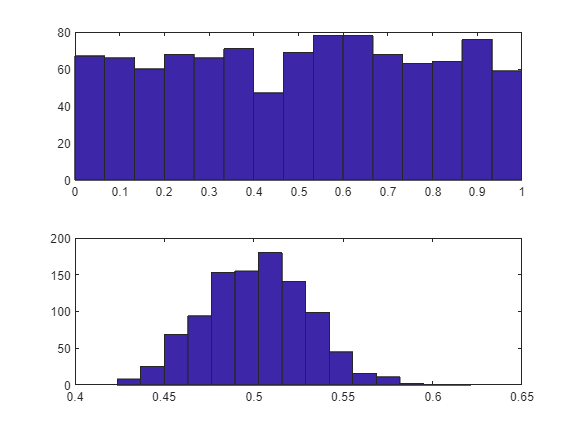

subplot(2,1,1); hist(x,Nbin);
subplot(2,1,2); hist(xavg_smp,Nbin);

Now lets compute the standard deviation of this sampling distribution

xavg_dev=std(xavg_smp)

xavg_dev = 0.0292

This is the 'standard error of the mean'. We can compare this with the theoretical value of the standard error

stderr=std(x)/sqrt(smpsz)

stderr = 0.0286

The two values compare quite well! This is because we resampled the data many times, i.e. we used large value for Nsmp. 

Note that in this case resampling was not needed, because we already have a theoretical formula for the standard error of the mean. However, resampling can be used with any 'statistic', i.e. any function of a dataset. For instance, you might want to fit a complicated population dynamics model to some demographic time series. The model parameters (e.g. birth rate, death rate, carrying capacity, etc.) are all 'statistics' of your data set. You can use resampling to estimate the error in your parameter estimation. In this case you could use the jacknife method, which recomputes the parameters by 'leaving one point out' of the data set.